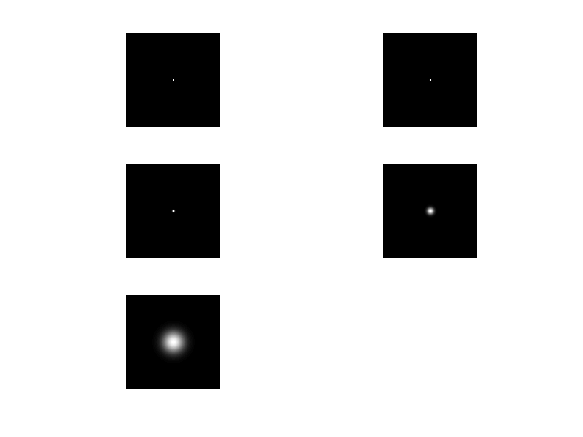

ans = 0.2501

ans = 0.3192

ans = 1.0000

ans = 10.0000

ans = 100.0000

% first plot the input responses and then with different pictures. 
plotId = 1;
figure;
for t = [0.1 0.3 1 10 100]
    psf = gaussfft(deltafcn(128, 128), t);
    var = variance(psf);
    %variance(psf)
    subplot(3, 2, plotId);
    var(1,1)
    plotId = plotId + 1; 
    showfs(fftshift(psf))
end

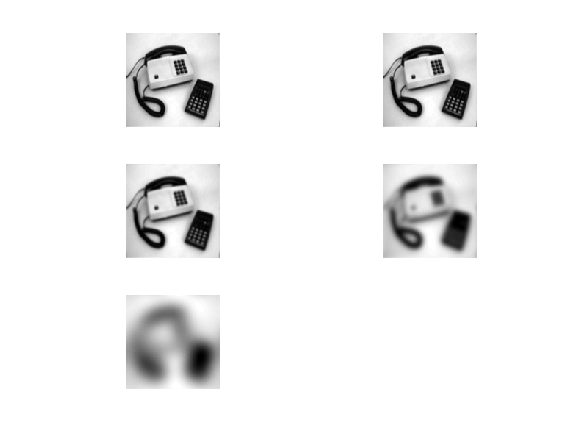


% q16
plotId = 1;
figure;
for t = [0.1 0.3 1 10 100]
    subplot(3, 2, plotId);
    psf = gaussfft(phonecalc128, t);
    plotId = plotId + 1; 
    showgrey(psf)
end